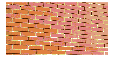

% Exercício 1
[Image,ColorMap] = imread("Parede_8bit.bmp");
figure(1)
imshow(Image,ColorMap);
title('Original Image')


% Exercício 2
Save8bitImage('Image2',Image)

% Exercício 3
[N,M,Im] = Load8bitImage('Image2');
figure(2)
imshow(Im,ColorMap);
title('Image 2 (same as original)')

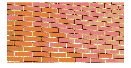


% Exercicio 4
Stream = EncodeImage_RLE(Image);

% Exercicio 5
Save8bitStream('ImageStream',N,M,Stream);

% Exercicio 6
[N,M,Stream6] = Load8bitStream('ImageStream');

% Exercicio 7
Image7 = DecodeImage_RLE(N,M,Stream);
figure(3)
imshow(Image7,ColorMap);
title('Decoded Image (same as original, smaller size')